%EE 354
%Homework 5
%Lisa Jacklin
% 10/1/2022
%Computer Exercised 3A is simply the general background

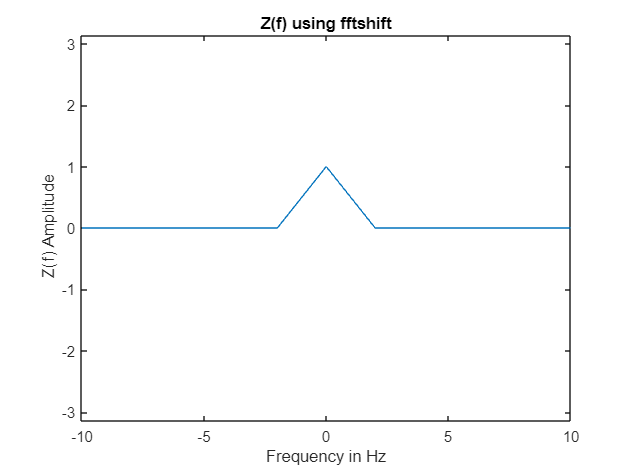

%Computer Exercise 3B

%generate the RF pulse of example 2.3-2
%z(t) = A rect (t/tc)cos (wct)
%Z(f) = Atc/2 sinc(f-fc)tc +Atc/2 sinc (f+fc)tc

%z(t) transferred into code.
tstart = 0;
tc = 1;
tend = 10.23;
time = tstart:tc:tend;

A = 1; %assuming the amplitude is 1
fs = 100; %sampling frequency
tsamp = 1/fs;


z = A.*rectpuls(time/tsamp).*cos(time);

freq = -(fmax/2):2:fmax/2;

%time shift of 5 seconds 
y= fftshift(z);
plot (freq, y);
    axis([-10 10 -pi pi])
    ylabel(" Z(f) Amplitude")
    xlabel('Frequency in Hz')
    title ("Z(f) using fftshift")

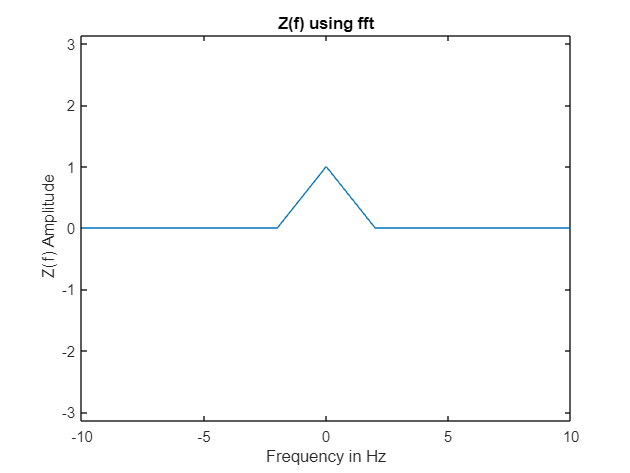

%part b
tstat = -5;
te = 5.23;

time2 = tstat:1:te;
%fs remains the same 100Hz sampling so is not added another time.

x = fftshift(z); %fft was not giving the corrent inputs vs fftshift
plot (freq, x)
    axis([-10 10 -pi pi])
    ylabel(" Z(f) Amplitude")
    xlabel('Frequency in Hz')
    title ("Z(f) using fft")

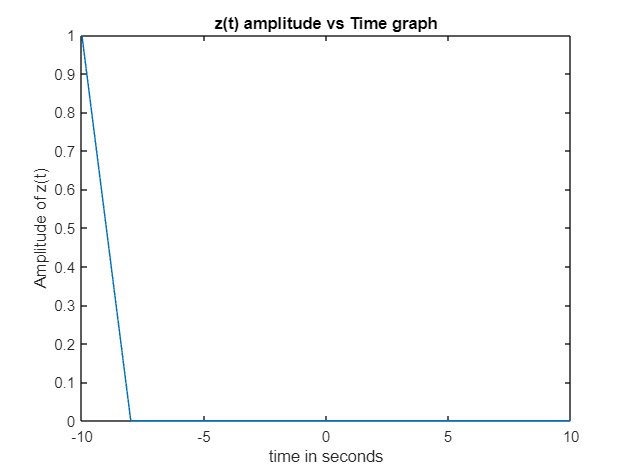

%computer exercise 3B.1
%plot the RF pulse as a function of time.

plot (freq, z) %this should give the function of time which was used for both part 
%a and part b in 3B. 
    title ("z(t) amplitude vs Time graph")
    xlabel ("time in seconds")
    ylabel ("Amplitude of z(t)")

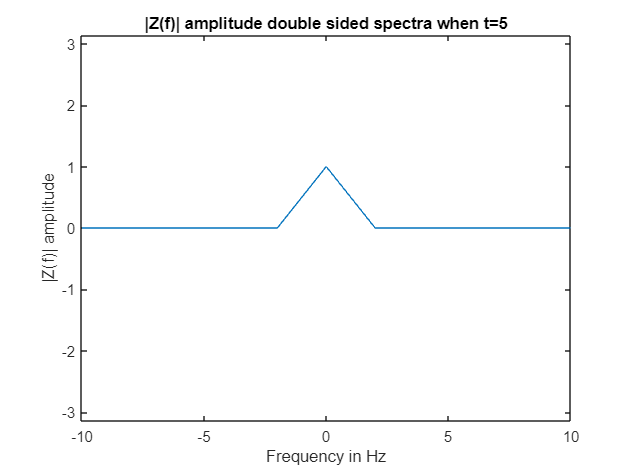

%Computer Exercise 3B.2
%plot the amplitude and phase spectra, double sided of the pulses.

%abs will be used here as well as angle
%taking from part 3B a and b, the angle and phase will be plotted of each
%note x is centered at zero and y is centered at 5.

plot (freq, abs(y))
    title ("|Z(f)| amplitude double sided spectra when t=5")
    axis([-10 10 -pi pi])
    xlabel('Frequency in Hz')
    ylabel("|Z(f)| amplitude")

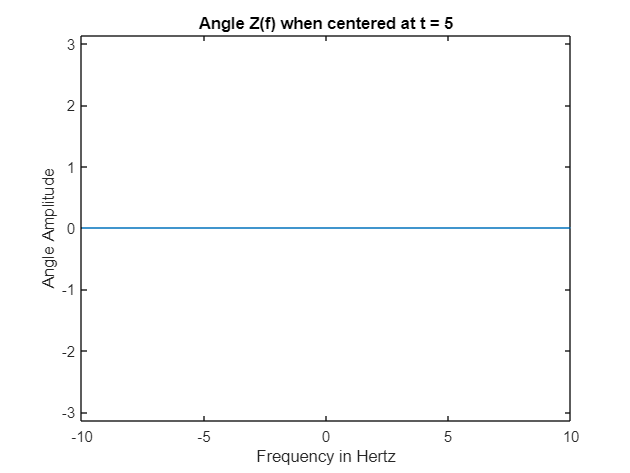

%now for y angle
plot (freq, angle(y)) %CHECK THIS PLEASE
    axis([-10 10 -pi pi])
    title ("Angle Z(f) when centered at t = 5")
    xlabel("Frequency in Hertz")
    ylabel("Angle Amplitude")

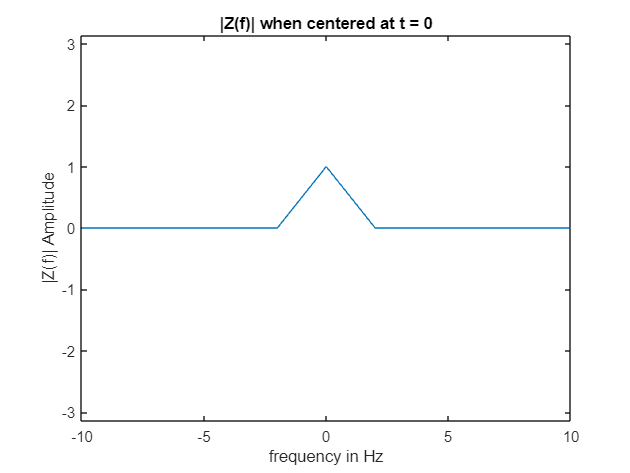


plot (freq, abs(x))
    axis([-10 10 -pi pi])
    title ('|Z(f)| when centered at t = 0')
    xlabel ('frequency in Hz')
    ylabel('|Z(f)| Amplitude')

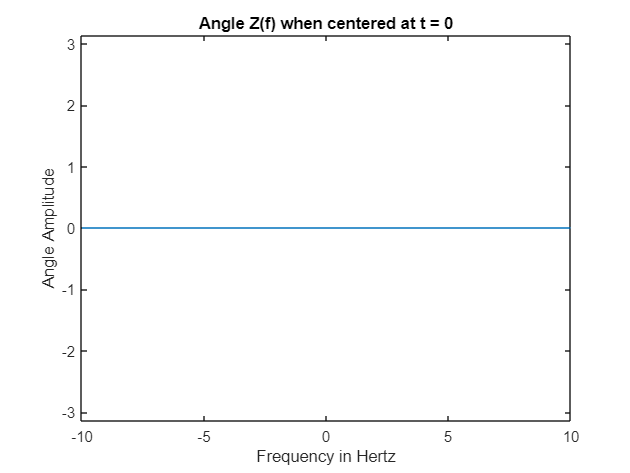

%next is x angle spectra
plot (freq, angle(x)) %CHECK THIS PLEASE
    axis([-10 10 -pi pi])
    title ("Angle Z(f) when centered at t = 0")
    xlabel("Frequency in Hertz")
    ylabel("Angle Amplitude")

%Computer Exercise 3B.3
%discuss the  positive frequency of each amplitude and phase spectra.
%range 7-13 Hz.

%discuss results:
%     The difference between the first function Z(f) and the second Z(f) come from the fourier transform shift which in the 
%     time domain is 5 seconds. This changes the center point of each of the fourier equations, resulting in different 
%     symetries across the y axis, as well as resulting odd symmetry when considering the angle of each of these functions.

